fileNames = { % text file 읽어오기
    'EXP-40bpm2-000_00B4BB52.txt', 'data_FOOT', 'foot_exo_off';
    'EXP-40bpm2-000_00B4BAF3.txt', 'data_SHANK', 'shank_exo_off';
    'EXP-40bpm2-000_00B4BA83.txt', 'data_THIGH', 'thigh_exo_off';
    'EXP-40bpm2-000_00B4BB4F.txt', 'data_foot', 'foot_exo_on';
    'EXP-40bpm2-000_00B4BB4E.txt', 'data_shank', 'shank_exo_on';
    'EXP-40bpm2-000_00B4BB4D.txt', 'data_thigh', 'thigh_exo_on'
};

fields = {'PacketCounter', 'acc_x', 'acc_y', 'acc_z', 'gyro_x', 'gyro_Y', 'gyro_Z', 'roll', 'pitch', 'yaw'};

for i = 1:size(fileNames, 1)
    fileID = fopen(fileNames{i, 1}, 'r');
    data = textscan(fileID, '%d %f %f %f %f %f %f %f %f %f', 'HeaderLines', 14);
    fclose(fileID);
    assignin('base', fileNames{i, 2}, data);

    dataStruct = struct(); %구조체 할당
    for j = 1:length(fields) % 각 field 에 저장
        dataStruct.(fields{j}) = data{j};
    end
    assignin('base', fileNames{i, 3}, dataStruct);
end

label_fontsz=16

label_fontsz = 16

title_fontsz=18

title_fontsz = 18

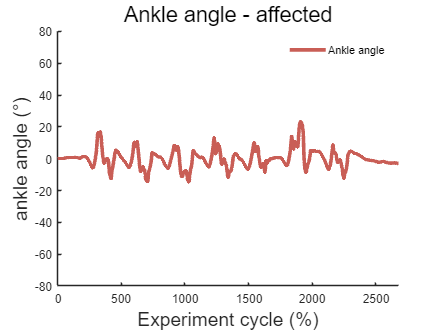


ankle_exo_on = calculate_rotation_angles(foot_exo_on.roll, foot_exo_on.pitch, foot_exo_on.yaw, shank_exo_on.roll, shank_exo_on.pitch, shank_exo_on.yaw);
%knee_exo_on = calculate_rotation_angles(shank_exo_on.roll, shank_exo_on.pitch, shank_exo_on.yaw, thigh_exo_on.roll, thigh_exo_on.pitch, thigh_exo_on.yaw);

% Calculate the mean of the first 10 values
ankle_exo_on_mean = mean(ankle_exo_on(1:10));
%knee_exo_on_mean = mean(knee_exo_on(1:10));

% Subtract the mean from each angle
ankle_exo_on = ankle_exo_on - ankle_exo_on_mean;
%knee_exo_on = knee_exo_on - knee_exo_on_mean;

figure; 
hold on;
plot(ankle_exo_on, 'LineStyle','-','Color',[201/255,94/255,86/255], 'LineWidth', 3);
%plot(knee_exo_on, 'LineStyle','-','Color',[130/255,162/255,220/255], 'LineWidth', 2.3);

xlabel('Experiment cycle (%)', 'FontSize', label_fontsz); % x축 레이블 폰트 크기 조정
ylabel('ankle angle (°)', 'FontSize', label_fontsz); % y축 레이블 폰트 크기 조정
title('Ankle angle - affected', 'FontSize', title_fontsz); % 타이틀 폰트 크기 조정
xlim([0, length(ankle_exo_on)]);
ylim([-80,80])
legend('Ankle angle','Box','off');
hold off;

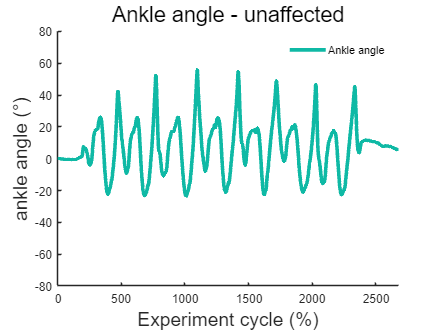

ankle_exo_off = calculate_rotation_angles(foot_exo_off.roll, foot_exo_off.pitch, foot_exo_off.yaw, shank_exo_on.roll, shank_exo_on.pitch, shank_exo_on.yaw);
% Calculate the mean of the first 10 values
ankle_exo_off_mean = mean(ankle_exo_off(1:10));

% Subtract the mean from each angle
ankle_exo_off = ankle_exo_off - ankle_exo_off_mean;

figure; 
hold on;
plot(ankle_exo_off, 'LineStyle','-','Color',[15/255, 185/255, 165/255], 'LineWidth', 3);

xlabel('Experiment cycle (%)', 'FontSize', label_fontsz); % x축 레이블 폰트 크기 조정
ylabel('ankle angle (°)', 'FontSize', label_fontsz); % y축 레이블 폰트 크기 조정
title('Ankle angle - unaffected', 'FontSize', title_fontsz); % 타이틀 폰트 크기 조정
xlim([0, length(ankle_exo_off)]);
ylim([-80,80])
legend('Ankle angle','Box','off');
hold off;

function angle = rotation_matrix_to_angle(R)
    angle = acos((trace(R) - 1) / 2);
end
function R = euler_to_rotation_matrix(roll, pitch, yaw)
    R_x = [1, 0, 0;
           0, cos(roll), -sin(roll);
           0, sin(roll), cos(roll)];
    
    R_y = [cos(pitch), 0, sin(pitch);
           0, 1, 0;
           -sin(pitch), 0, cos(pitch)];
    
    R_z = [cos(yaw), -sin(yaw), 0;
           sin(yaw), cos(yaw), 0;
           0, 0, 1];
       
    R = R_z * R_y * R_x;
end
function angles = calculate_rotation_angles(rolls1, pitches1, yaws1, rolls2, pitches2, yaws2)
    % 배열의 길이
    n = length(rolls1);
    
    % 결과를 저장할 배열
    angles = zeros(1, n);
    
    for i = 1:n
        % 현재 값 radian으로 변환
        roll1 = deg2rad(rolls1(i));
        pitch1 = deg2rad(pitches1(i));
        yaw1 = deg2rad(yaws1(i));
        
        roll2 = deg2rad(rolls2(i));
        pitch2 = deg2rad(pitches2(i));
        yaw2 = deg2rad(yaws2(i));
        
        % Euler angles to rotation matrix
        R1 = euler_to_rotation_matrix(roll1, pitch1, yaw1);
        R2 = euler_to_rotation_matrix(roll2, pitch2, yaw2);
        
        % Relative rotation matrix
        R_relative = R1' * R2;
        
        % Rotation matrix to angle
        angle = rotation_matrix_to_angle(R_relative);
        
        % Degree로 변환
        angles(i) = rad2deg(angle);
    end
end
